# This is an example of the validation of parameter gamma in ridge regression using the data for homework 5

## Load the data

clear all
load('data5.mat')

## Split it in 80% training, 20% test (give or take)

Xtr=Xtrain(1:64,:);     % 64 samples is roughly 80% of the samples xtrain.
Xval=Xtrain(65:end,:);  % Remaining 20% of data
ytr=ytrain(1:64);       % 64 samples is roughly 80% of the samples ytrain.
yval=ytrain(65:end);    % Remaining 20% of data

## Setup the parameters to sweep

gamma=logspace(-2,4,10000);
% gamma=logspace(-5,1,100);   % Interval for gamma as suggested in prompt.
I=eye(19);


## Ridge regression training and validation 

for i=1:length(gamma)
    w=pinv(Xtr'*Xtr+gamma(i)*I)*Xtr'*ytr;   % training
    y=w'*Xval';                             % validation
    E(i)=mean((yval-y').^2);                % validation error
%     testE(i)=mean((ytest-ytrain).^2);       % test error
end


## Training again with the best gamma

[e,ind]=min(E);
% [er,inx]=min(testE);
w=pinv(Xtr'*Xtr+gamma(ind)*I)*Xtr'*ytr; 


## Test

y_output=w'*Xtest'; % Using Xtest given in data file, w uses best gamma. 


## Plot linear ridge regression

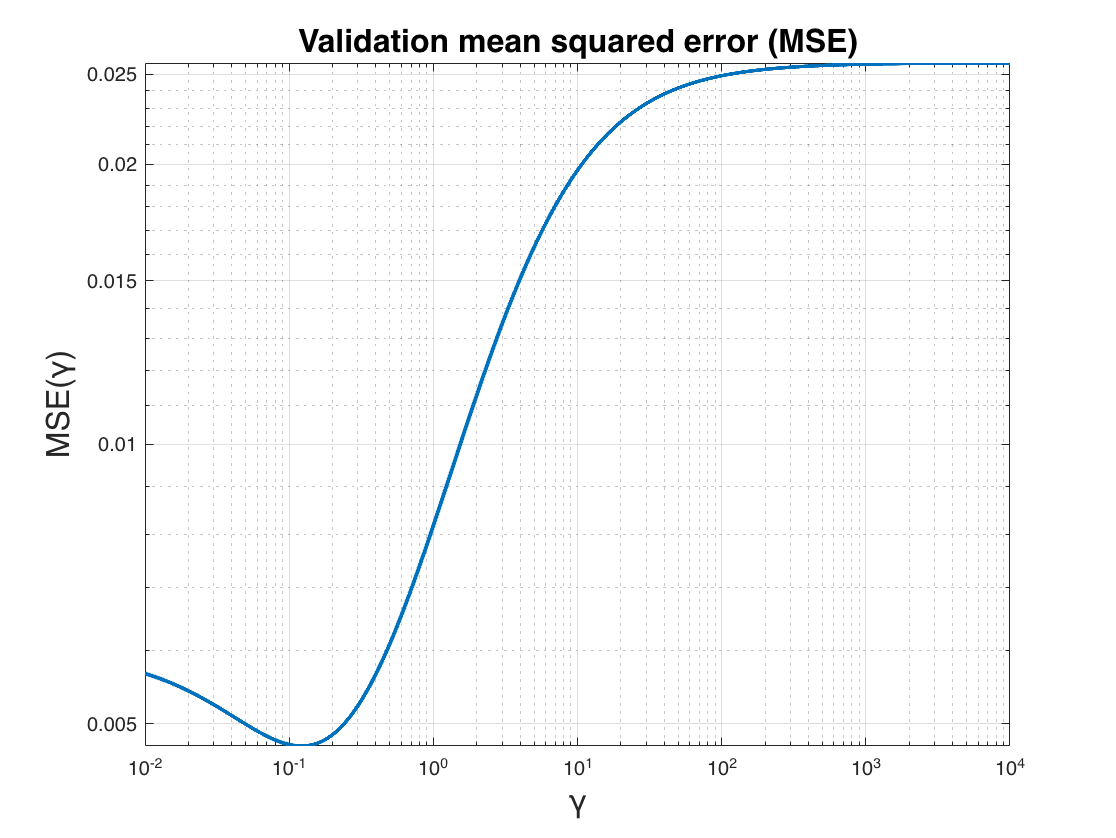

figure(1);
loglog(gamma,E,'Linewidth',2)
grid on; grid minor;
xlabel('\gamma','FontSize',16)
ylabel('MSE(\gamma)','FontSize',16)
title('Validation mean squared error (MSE)','FontSize',16)

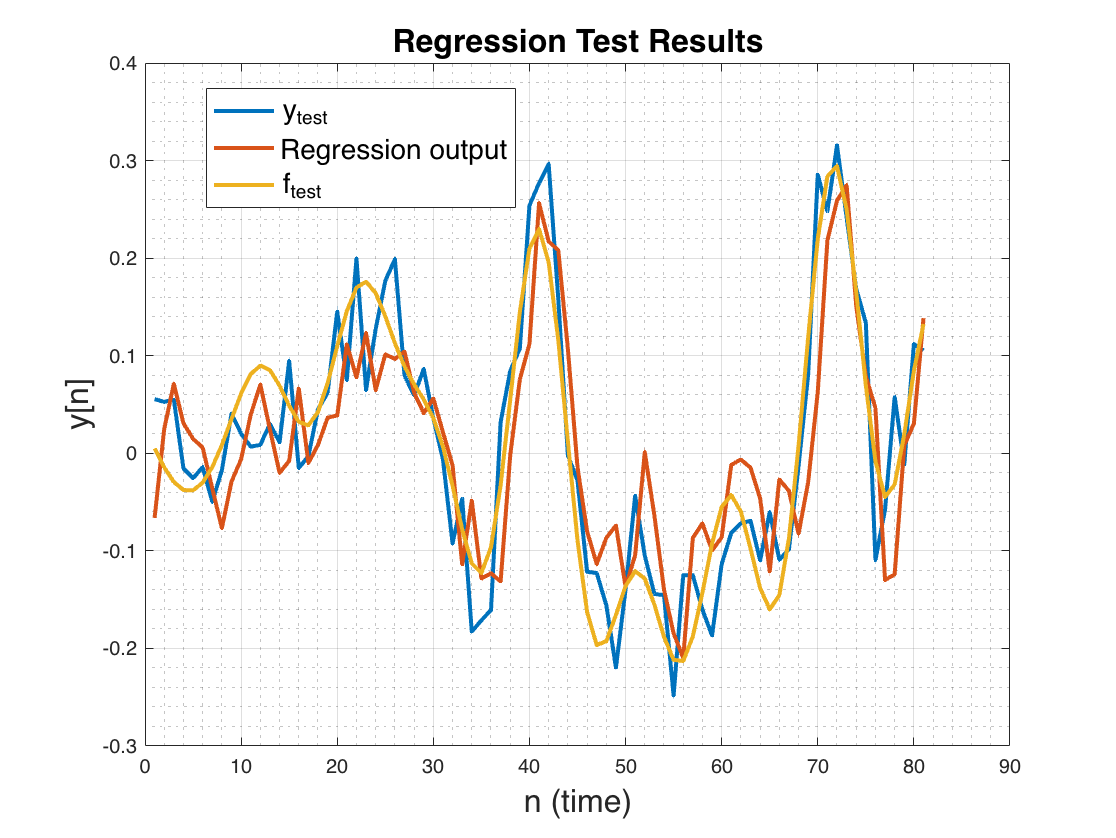


figure(2);
plot(ytest,'Linewidth',2)   % ytest as given in data file (no alterations).
hold on
plot(y_output,'Linewidth',2)
plot(ftest,'Linewidth',2)
grid on; grid minor;
xlabel('n (time)','FontSize',16)
ylabel('y[n]','FontSize',16)
legend('y_{test}','Regression output','f_{test}','FontSize',14,'Location','best')
title('Regression Test Results','FontSize',16)
hold off

## SVR training and validation

eps = logspace(-5,-.1,100);
Ieps = eye(19);
for i=1:length(eps)
    coefs=sprintf('-s 3 -t 0 -p %f -c 100 -h 0', eps(i));
    modelsvr = svmtrain(Xtr, ytr,coefs);
    wsvr = modelsvr.SVs'*modelsvr.sv_coef*Xtr'*ytr;
    y_outsv=wsvr'*Xval';                           %validation
    EV(i)=mean((yval-y_outsv').^2);              %validation error  
end

............*
optimization finished, #iter = 1576
nu = 0.991430
obj = -599.050683, rho = -0.012867
nSV = 64, nBSV = 62
............*
optimization finished, #iter = 1576
nu = 0.991430
obj = -599.044338, rho = -0.012867
nSV = 64, nBSV = 62
............*
optimization finished, #iter = 1576
nu = 0.991430
obj = -599.031648, rho = -0.012868
nSV = 64, nBSV = 62
............*
optimization finished, #iter = 1576
nu = 0.991430
obj = -599.025302, rho = -0.012868
nSV = 64, nBSV = 62
............*
optimization finished, #iter = 1576
nu = 0.991430
obj = -599.012612, rho = -0.012868
nSV = 64, nBSV = 62
............*
optimization finished, #iter = 1577
nu = 0.991411
obj = -599.000915, rho = -0.013185
nSV = 64, nBSV = 61
............*
optimization finished, #iter = 1577
nu = 0.991414
obj = -598.988071, rho = -0.013185
nSV = 64, nBSV = 61
............*
optimization finished, #iter = 1577
nu = 0.991417
obj = -598.975228, rho = -0.013185
nSV = 64, nBSV = 61
............*
optimization finished, #iter = 156

[eSVR,indSVR]=min(EV);
coefs=sprintf('-s 4 -t 0 -n %f -c 100 -h 0', eps(indSVR));
modelsvr2 = svmtrain(Xtr, ytr,coefs);

.....*
optimization finished, #iter = 641
epsilon = 0.144419
obj = -304.120728, rho = -0.019451
nSV = 16, nBSV = 13


wsvr = modelsvr2.SVs'*modelsvr2.sv_coef*Xtr'*ytr;
y_outSVR = wsvr'*Xtest';
% %Construction of the classifier with the model parameters
%  model = svmtrain(Xtr, ytr, '-s 3 -t 0 -p 0.5 -c 100');
% %Graphical representation of SVM
%  [predicted_label, accuracy, prob_estimates] = svmpredict(ytr,Xtr,model);
% %Dual Parameter w
%  wSVR = model.SVs'*model.sv_coef*Xtr'*ytr;
%  y_outSVR = wSVR'*Xtest';
%  for i=1:length(gamma)
%       EV(i)=mean((yval-y_outSVR(65:end)').^2);
%  end
%  [eSVR,indSVR]=min(EV);

## Plot SVR

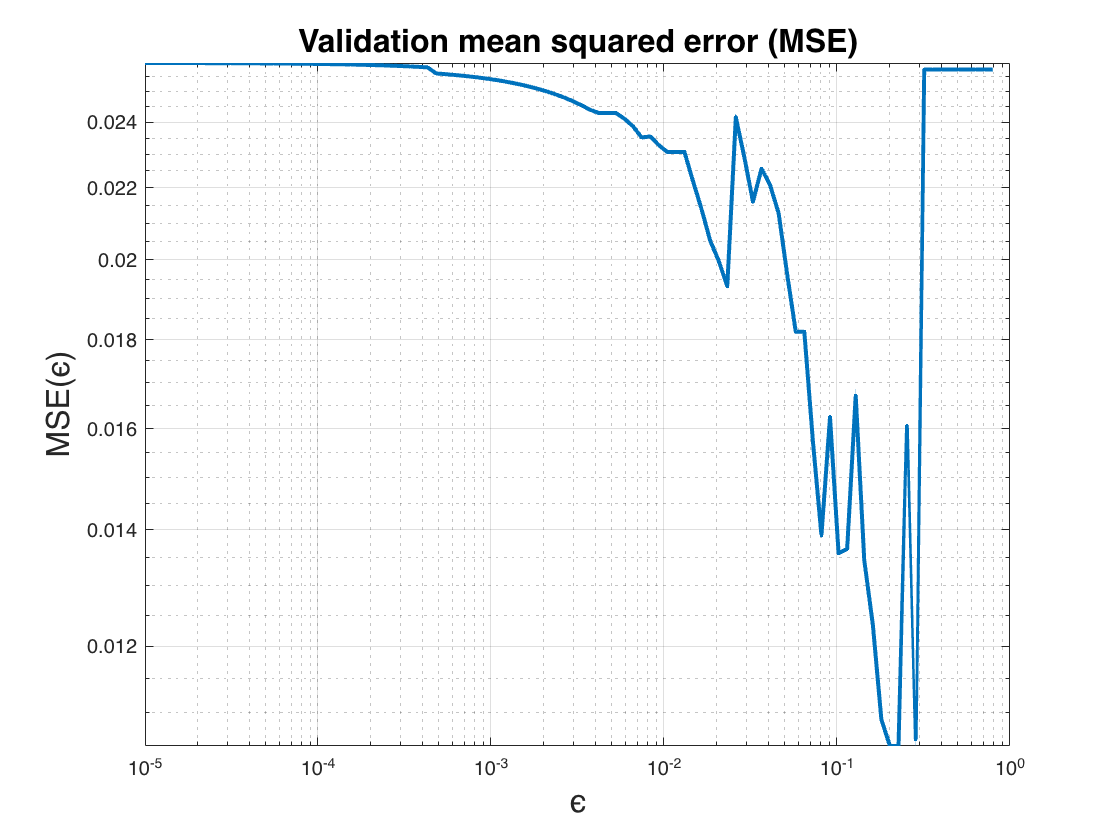

figure(3)
loglog(eps,EV,'Linewidth',2)
grid on; grid minor;
xlabel('\epsilon','FontSize',16)
ylabel('MSE(\epsilon)','FontSize',16)
title('Validation mean squared error (MSE)','FontSize',16)

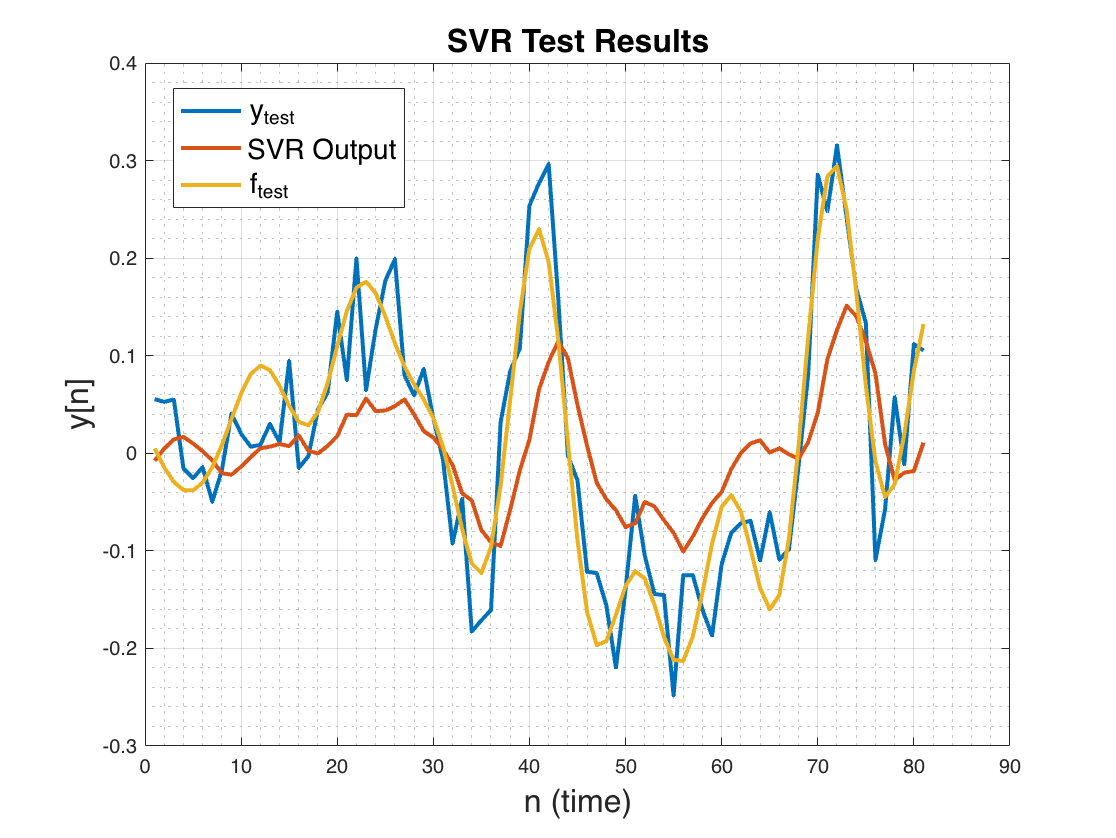


figure(4)
plot(ytest,'Linewidth',2)       % ytest values as given in data5.mat file. (No alterations)
hold on
plot(y_outSVR,'Linewidth',2)    % See Test section,
plot(ftest,'Linewidth',2)       % ftest data as given from data5.mat file
grid on; grid minor;
xlabel('n (time)','FontSize',16)
ylabel('y[n]','FontSize',16)
legend('y_{test}','SVR Output','f_{test}','FontSize',14,'Location','best')
title('SVR Test Results','FontSize',16)
hold off

## nu-SVR training and validation

%% Using nu-SVR method
nu = logspace(-5,-.1,100);
Inu = eye(19);
for i=1:length(nu)
    coefs=sprintf('-s 4 -t 0 -n %f -c 100', nu(i));
    modelnu = svmtrain(Xtr, ytr,coefs);
    wnu = modelnu.SVs'*modelnu.sv_coef*Xtr'*ytr;
    y_outNum=wnu'*Xval';                           %validation
    EVN(i)=mean((yval-y_outNum').^2);              %validation error  
end

*
optimization finished, #iter = 3
epsilon = 0.318888
obj = -0.020415, rho = 0.004406
nSV = 2, nBSV = 0
*
optimization finished, #iter = 3
epsilon = 0.318869
obj = -0.022456, rho = 0.004403
nSV = 2, nBSV = 0
*
optimization finished, #iter = 3
epsilon = 0.318833
obj = -0.026537, rho = 0.004396
nSV = 2, nBSV = 0
*
optimization finished, #iter = 3
epsilon = 0.318814
obj = -0.028577, rho = 0.004393
nSV = 2, nBSV = 0
*
optimization finished, #iter = 3
epsilon = 0.318777
obj = -0.032658, rho = 0.004386
nSV = 2, nBSV = 0
*
optimization finished, #iter = 3
epsilon = 0.318741
obj = -0.036738, rho = 0.004380
nSV = 2, nBSV = 0
*
optimization finished, #iter = 3
epsilon = 0.318704
obj = -0.040818, rho = 0.004374
nSV = 2, nBSV = 0
*
optimization finished, #iter = 3
epsilon = 0.318667
obj = -0.044897, rho = 0.004367
nSV = 2, nBSV = 0
*
optimization finished, #iter = 3
epsilon = 0.318612
obj = -0.051015, rho = 0.004357
nSV = 2, nBSV = 0
*
optimization finished, #iter = 3
epsilon = 0.318557
obj = -0.0

[enu,indNU]=min(EVN);
coefs=sprintf('-s 4 -t 0 -n %f -c 100', nu(indNU));
modelnu2 = svmtrain(Xtr, ytr,coefs);

*
optimization finished, #iter = 3
epsilon = 0.301512
obj = -1.896503, rho = 0.001352
nSV = 2, nBSV = 0


wnum = modelnu2.SVs'*modelnu2.sv_coef*Xtr'*ytr;
y_outNu = wnum'*Xtest';
% %Construction of the classifier with the model parameters 
%  modelnu = svmtrain(Xtr, ytr, '-s 4 -t 0 -n 0.01 -c 100');
% %Graphical representation of SVM
%  [predicted_label, accuracy, prob_estimates] = svmpredict(ytr,Xtr,modelnu);
% %Dual Parameter w
%  wnu = modelnu.SVs'*modelnu.sv_coef*Xtr'*ytr;
%  y_outNu = wnu'*Xtest';
%  for i=1:length(gamma)
%       EVN(i)=mean((yval-y_outNu(65:end)').^2);
%  end
%  [enu,indNU]=min(EVN);

## Plot nu-SVR

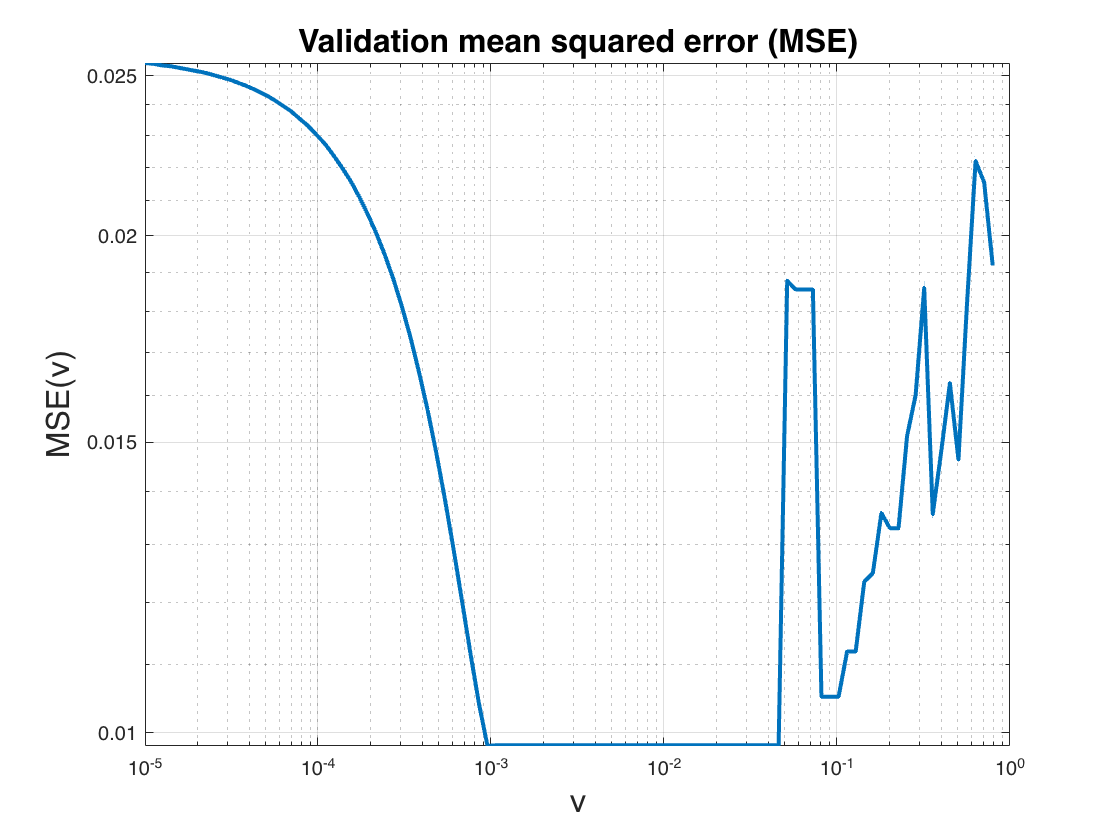

figure(5)
loglog(nu,EVN,'Linewidth',2)
grid on; grid minor;
xlabel('\nu','FontSize',16)
ylabel('MSE(\nu)','FontSize',16)
title('Validation mean squared error (MSE)','FontSize',16)

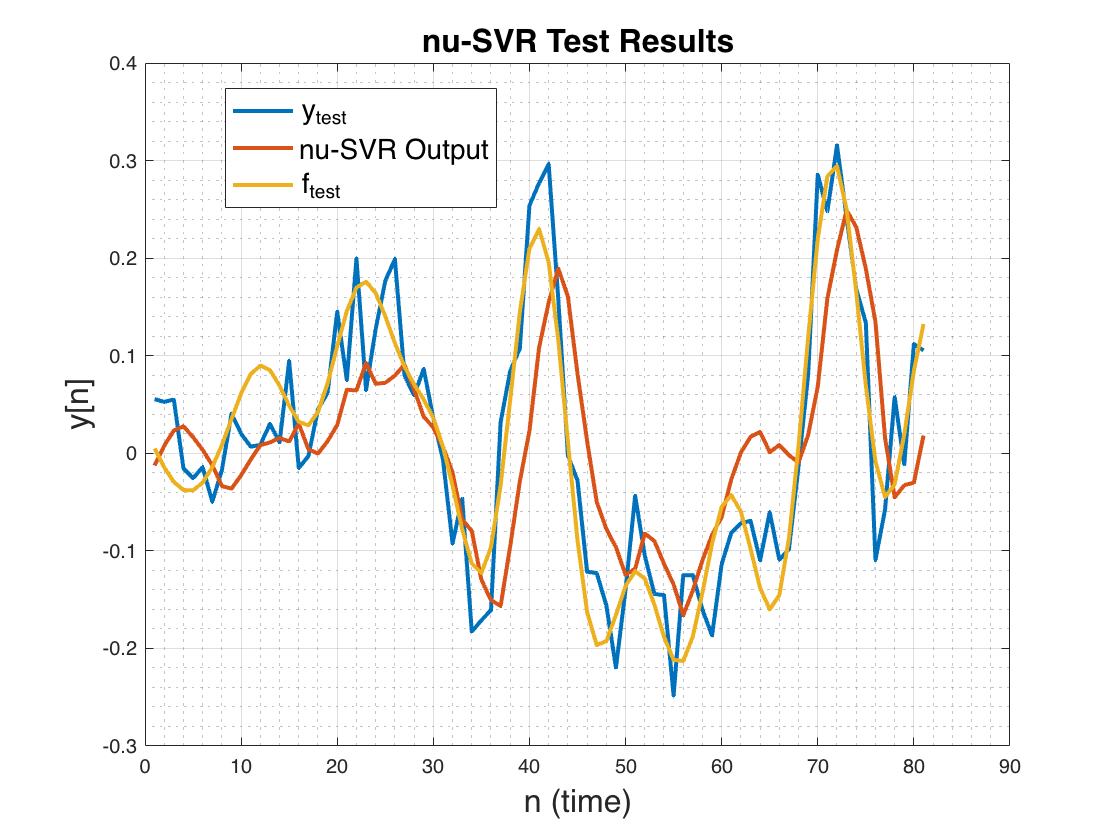


figure(6)
plot(ytest,'Linewidth',2)       % ytest values as given in data5.mat file. (No alterations)
hold on
plot(y_outNu,'Linewidth',2)     % See Test section,
plot(ftest,'Linewidth',2)       % ftest data as given from data5.mat file
grid on; grid minor;
xlabel('n (time)','FontSize',16)
ylabel('y[n]','FontSize',16)
legend('y_{test}','nu-SVR Output','f_{test}','FontSize',14,'Location','best')
title('nu-SVR Test Results','FontSize',16)
hold off 